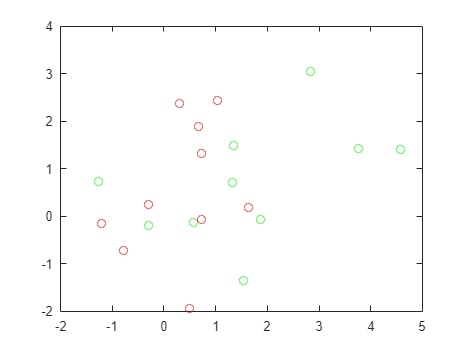

% 使用贝叶斯优化来优化 SVM 分类器拟合
% 此示例说明如何使用 fitcsvm 函数和 OptimizeHyperparameters 名称-值对组优化 SVM 分类。
% 该分类基于高斯混合模型中点的位置来工作。有关该模型的描述，
% 请参阅 The Elements of Statistical Learning，
% 作者 Hastie、Tibshirani 和 Friedman (2009)，第 17 页。
% 该模型从为“green”类生成 10 个基点开始，这些基点呈二维独立正态分布，
% 均值为 (1,0) 且具有单位方差。它还为“red”类生成 10 个基点，
% 这些基点呈二维独立正态分布，均值为 (0,1) 且具有单位方差。
% 对于每个类（green 和 red），生成 100 个随机点，如下所示：
% 
% 随机均匀选择合适颜色的一个基点 m。
% 生成一个呈二维正态分布的独立随机点，其均值为 m，方差为 I/5，
% 其中 I 是 2×2 单位矩阵。在此示例中，使用方差 I/50 来更清楚地显示优化的优势。
% 生成点和分类器

% 为每个类生成 10 个基点。

rng default % For reproducibility
grnpop = mvnrnd([1,0],eye(2),10);
redpop = mvnrnd([0,1],eye(2),10);
% 查看基点。

plot(grnpop(:,1),grnpop(:,2),'go')
hold on
plot(redpop(:,1),redpop(:,2),'ro')
hold off

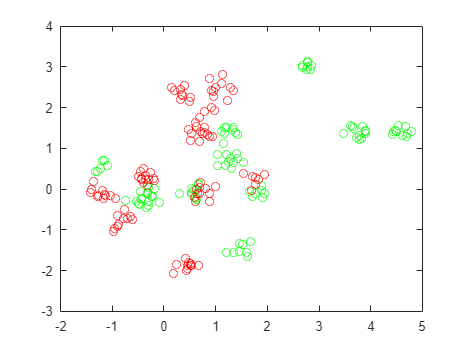



% 由于一些红色基点靠近绿色基点，因此很难仅基于位置对数据点进行分类。
% 生成每个类的 100 个数据点。

redpts = zeros(100,2);grnpts = redpts;
for i = 1:100
    grnpts(i,:) = mvnrnd(grnpop(randi(10),:),eye(2)*0.02);
    redpts(i,:) = mvnrnd(redpop(randi(10),:),eye(2)*0.02);
end
% 查看数据点。

figure
plot(grnpts(:,1),grnpts(:,2),'go')
hold on
plot(redpts(:,1),redpts(:,2),'ro')
hold off



% 为分类准备数据
% 
% 将数据放入一个矩阵中，并创建向量 grp，该向量标记每个点的类。

cdata = [grnpts;redpts];
grp = ones(200,1);
% Green label 1, red label -1
grp(101:200) = -1;

## 准备交叉验证

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |       0.195 |     0.26771 |       0.195 |       0.195 |       193.54 |     0.069073 |        false |
|    2 | Accept |       0.345 |    0.061657 |       0.195 |     0.20398 |       43.991 |       277.86 |        false |
|    3 | Accept |       0.365 |    0.073293 |       0.195 |     0.20784 |    0.0056595 |     0.042141 |        false |
|    4 | Accept |        0.61 |    0.098857 |       0.195 |     0.31714 |       49.333 |    0.0010514 |         true |
|    5 | Best   |         0.1 |    0.067007 |   

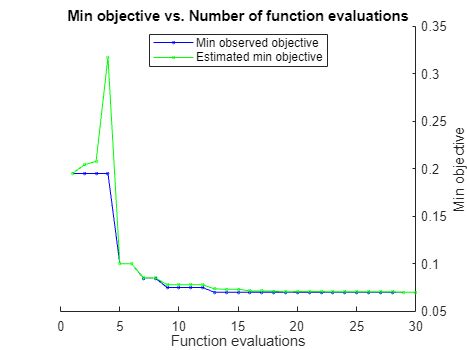

svmmod =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 200
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [66×1 double]
                                 Bias: -0.0911
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [200×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [200×1 logical]
                               Solver: 'SMO'


  Properties, Methods


% 为交叉验证设置一个分区。此步骤确定优化在每一步所使用的训练集和测试集。

c = cvpartition(200,'KFold',10);
% 优化拟合
% 
% 要找到好的拟合，即交叉验证损失低的拟合，请设置选项以使用贝叶斯优化。在所有优化中使用相同的交叉验证分区 c。
% 
% 为了实现可再现性，请使用 'expected-improvement-plus' 采集函数。

opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',c,...
    'AcquisitionFunctionName','expected-improvement-plus');
svmmod = fitcsvm(cdata,grp,'KernelFunction','rbf',...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',opts)


% 计算优化模型的损失。

lossnew = kfoldLoss(fitcsvm(cdata,grp,'CVPartition',c,'KernelFunction','rbf',...
    'BoxConstraint',svmmod.HyperparameterOptimizationResults.XAtMinObjective.BoxConstraint,...
    'KernelScale',svmmod.HyperparameterOptimizationResults.XAtMinObjective.KernelScale))

lossnew = 0.0700

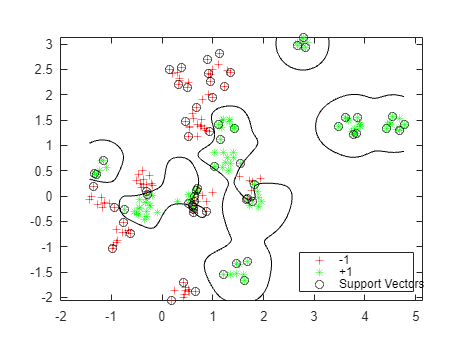

% lossnew = 0.0650
% 该损失与“观测的目标函数值”下优化输出中报告的损失相同。
% 
% 可视化经过优化的分类器。

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(cdata(:,1)):d:max(cdata(:,1)),...
    min(cdata(:,2)):d:max(cdata(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(svmmod,xGrid);
figure;
h = nan(3,1); % Preallocation
h(1:2) = gscatter(cdata(:,1),cdata(:,2),grp,'rg','+*');
hold on
h(3) = plot(cdata(svmmod.IsSupportVector,1),...
    cdata(svmmod.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'},'Location','Southeast');
axis equal
hold off